# **Dynamics**

# `22320631`

# `Zhang Yichong `

The purpose of the following script is to help students with mastering the knowledge about **the dynamics of complex rigid bodies systems**. The student is **learning by doing **the concerete task. During subsequent steps developed inside the script, the student has the opportunity to practice the following skills:

- fill in the free body diagram of rigid body;

- write down equations of the resultant force, according to Newton's principle of dynamics;

- write down equations of kinematic constraints, combining the values of acceleration of systems elements;

- determine the numerical solution for given values of the model parameters.

The error in execution of the script indicated by MATLAB results from the tests carried out at the end of each section. Each test checks the correctness of the entered by the student data. Thanks to this, the student gets** immediate feedback** and verification of the gained knowledge. 

(The solution of the script is in the file dynamics_solution.mlx.)

# Task definition

The analyzed system is shown in Figure 1. The system is located in the Earth's gravitational field.

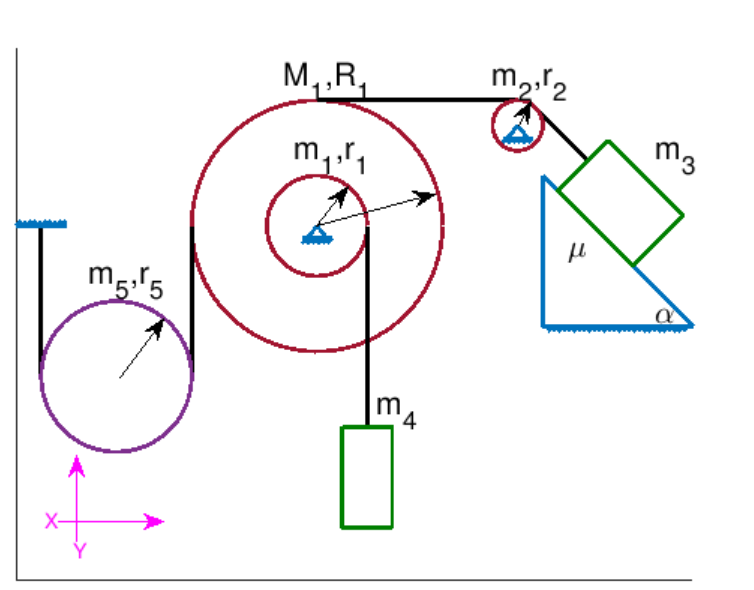

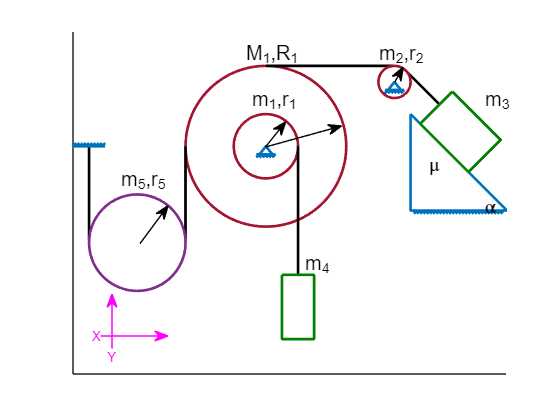

Fig 1. Schema of rigid bodies system


clc; clear;
draw_all;

The system consists of: 

- two rigidly connected pulleys with masses $m_1$, $M_{1}$ and radii $r_{1}$, $R_{1}$, that can rotate without any friction around a fixed axis of symmetry;

- a pulley with a mass $m_2$ and radius $r_{2}$, that can rotate without any friction around a fixed axis of symmetry;

- a block with a mass $m_3$ sliding on an inclined plane;

- a hanging brick with a weight $m_4$;

- a hanging pulley with a mass $m_5$ and radius $r_{5}$, that can rotate around an axis of symmetry and move in a vertical direction;

- a fixed incline with an angle of inclination $\alpha$;

- non-stretchable cord, connecting elements of the system.

The coefficient of friction between the $m_3$ block and the inclined plane is $\mu$. We assume, that under the influence of the gravity field, the block $m_4$ moves down. The mass parameters, radii of pulleys, angle of inclination and the sliding friction coefficient between the block and the inclined plane are given.

syms g mu alpha;
syms m1 M1 m2 m3 m4 m5;
syms r1 R1 r2 r5;

The gravitational force is proportional to the acceleration of the Earth $g$ and the mas $Q=m*g$. The weight of systems elements is described by following dependencies. 

**Please fill in the following equations: **

Q1=m1*g+M1*g;                   %(0.1)
Q2=m2*g;                        
Q3=m3*g;                        
Q4=m4*g;
Q5=m5*g;

The moment of inertia describes the mass distribution of pulleys. For homogeneous pulleys, the moment of inertia is described by: $I=\frac{m*r^2}{2}$. 

**Please fill in the equations describing the moments of inertia of pulley 1, 2 and 5:**

I1=0.5*m1*r1^2+0.5*M1*R1^2;
I2=0.5*m2*r2^2;
I5=0.5*m5*r5^2;

In the task we are looking for the values of linear:

syms a2 a3 a4 a5 a5o;               %(1.1)

and angular: 

syms e1 e2 e5;                      %(1.2)

accelerations of the elements of the system.

The unknowns are also: 

- the reaction forces in supports:

syms R1x R1y R2x R2y;               %(1.3)

- the tension in the chords:

syms S1 S2 S3 S4 S5;                %(1.4)

- friction:

syms T3;                            %(1.5)

- and substrate reaction.

syms N3;                            %(1.6)

In the task we have 19 unknown values. In order to solve the task, we need **19 equations.**

Checking of the equations:

test0;

# The 1st element  

## Free Body Diagram 

In the first step of solving the task, we divide the system into separate components. By releasing parts of the system from chains, we draw up free body diagrams showing all forces and moments of forces acting on subsequent elements. 

The 1st element of the system are two rigidly connected pulleys with masses of $m_1$, $M_1$ and radii $r_1$, $R_1$. These pulleys are mounted on a fixed support, placed in the pulleys axis of symmetry. We assume that the pulleys can rotate without friction around the point of attachment of the fixed support.

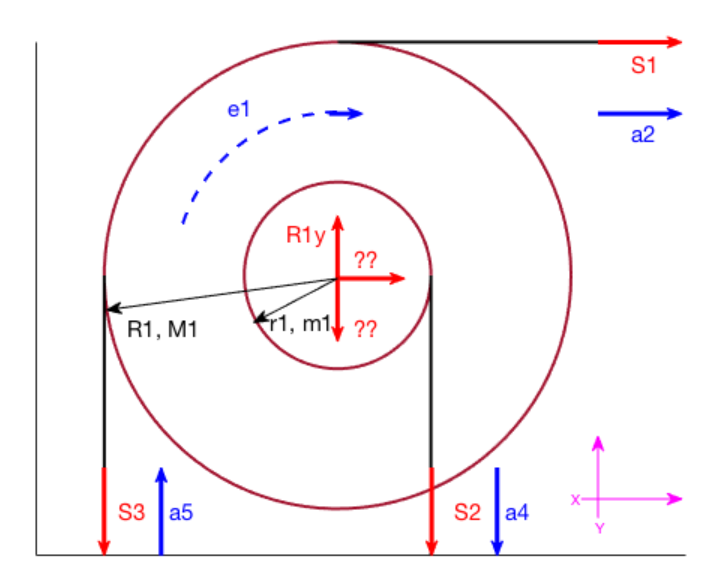S

According to the symbols adopted in the line %(1.2), the angular acceleration of the 1st element is equal:

p1='e1';

The linear acceleration, assigned in line %(1.1), of non-stretchable cords, shown in Figure 2 are equal:

p2='a2';
p3='a4';
p4='a5';

**Please fill in the remaining reaction forces in fixed supports, according to the symbols adopted in line %(1.3):**

F1='R1y';
F2='R1x';

**Please substitute the symbol describing the weight of the 1st element:**

F3='Q1';

The tension forces of the chords, defined in line %(1.4), were adopted as follows:

F4='S1';
F5='S2'; 
F6='S3';

Free Body Diagram of the 1st element is shown in Figure 2.

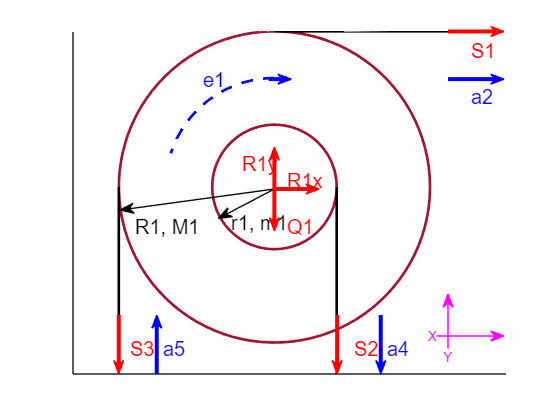

Fig 2. Free body diagram of the 1st element


draw_1;

## Dynamic equations of motion

The second principle of Newton's dynamics says, that the resultant force acting on the body along the given direction, is equal to the product of mass and acceleration in this direction $\sum F_{x}=m*a_{x}$. We assume, that the vectors of forces and accelerations, turned along the positive axis have the plus sign, while turned opposite have the negative values.

The 1st element of the system is mounted on a fixed support, so it can not move along the X axis of the inertial coordinate system. The X component of the resultant force, acting on the 1st element is therefore equal to zero. 

The equation describing the X component of the resultant force, acting on the 1st element has the following form:

L=R1x+S1;
P=sym(0);
feq1=(L==P);

The equations along the Y axis have an analogous form. 

**Fill in the left side of the equation, describing the Y component of the resultant force, acting on the 1st element:**

L=R1y-Q1-S2-S3;
P=sym(0);
feq2=(L==P);

The moment of force is defined as the product of the force and the arm on which it operates. In the case of a given task definition, the force arm is the radius of pulley$M=F*r$. According to the laws of dynamics for rotational motion, the resultant moment of force is equal to the product of the moment of inertia of the body and the angular acceleration $\sum M=I*\epsilon$. We assume that the positive direction of the moments is directed counter-clockwise (the positive direction of the Z axis, of the inertial right-handed coordinate system). The equation describing the equilibrium of moments of forces acting on the 1st element has the following form:

L=-S1*R1-S2*r1+S3*R1;
P=-I1*e1;
feq3=(L==P);

## Kinematic equations of motion

While solving the tasks from the dynamics of complex systems, kinematic equations should be defined next to force equations. Kinematic equations define the relations between the accelerations of individual elements of the system. The relation between the angular acceleration of the 1st element $\epsilon_1$ and the linear acceleration of chord connected to the 2nd element $a_{2}$ is described by the equation:

L=e1*R1;
P=a2;
keq1=(L==P);

**Fill in the left side of the kinematic equation, connecting the angular acceleration of the 1st element and linear acceleration of the chord **$a_4
$:

L=e1*r1;
P=a4;
keq2=(L==P);

**Fill in the left side of the kinematic equation, connecting the angular acceleration of the 1st element and linear acceleration of the chord **$a_5
$:

L=e1*R1;
P=a5;
keq3=(L==P);

Checking of the equations:

test1;

# The 2nd Element

## Free Body Diagram

The 2nd element of the system is pulley, with mass $m_2$ and radii $r_2$, hooked on a fixed support, mounted in the pulley axis of symmetry. We assume that the pulley can rotate without any friction around the point of attachment of the fixed support.

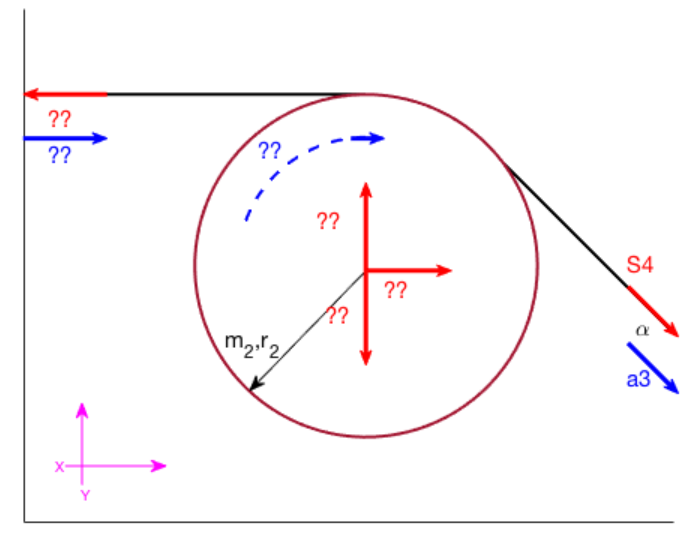

**According to the symbols adopted in line %(1.2), please fill in the angular acceleration of the 2nd element:**

p5='e2';

**According to the symbols shown in Figure 2, please fill in the linear acceleration of the chord connected to the 1st element:**

p6='a2';
p7='a3';

**By the analogy to the 1st element, please fill in the reaction forces in fixed support of the 2nd element, according to the symbols adopted in line %(1.3): **

F7='R2x';
F8='R2y';

**Please substitute the symbol describing the weight of the 2nd element:**

F9='Q2';

**According to the symbols shown in Figure 2 please fill in the tension force in the chord connected to the 1st element:**

F10='S1';
F11='S4';

Free Body Diagram of the 2nd element is shown in Figure 3.

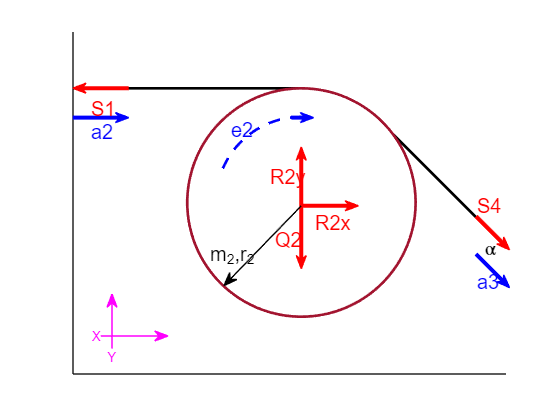

Fig 3. Free body diagram of the 2nd element


draw_2;

## Dynamic equations of motion

The 2nd element of the system is mounted on a fixed support, so it can not move along the X axis of the inertial coordinate system. The X component of the resultant force, acting on the 2nd element is therefore equal to zero. 

**Please fill in the left side of the equation, describing the X component of the resultant force acting on the 2nd element:**

L=R2x-S1+S4*cos(alpha);
P=sym(0);
feq4=(L==P);

The equations along the Y axis have an analogous form. 

**Please fill in the left side of the equation, describing the Y component of the resultant force acting on the 2nd element:**

L=R2y-Q2-S4*sin(alpha);
P=sym(0);
feq5=(L==P);

**Please fill in the left and right side of the equation, describing the resultant moments of force acting on the 2nd element:**

L=S1*r2-S4*r2;
P=-I2*e2;
feq6=(L==P);

## Kinematic equations of motion

**Fill in the left side of the kinematic equation, connecting the angular acceleration of the 2nd element and linear acceleration of the chord **$a_2
$:

L=e2*r2;
P=a2;
keq4=(L==P);

**Fill in the left side of the kinematic equation, connecting the angular acceleration of the 2nd element and linear acceleration of the chord **$a_3
$:

L=e2*r2;
P=a3;
keq5=(L==P);

Checking of the equations:

test2;

# The 3rd Element

## Free Body Diagram

The 3rd element of the system is block slinding down from the fixed incline. 

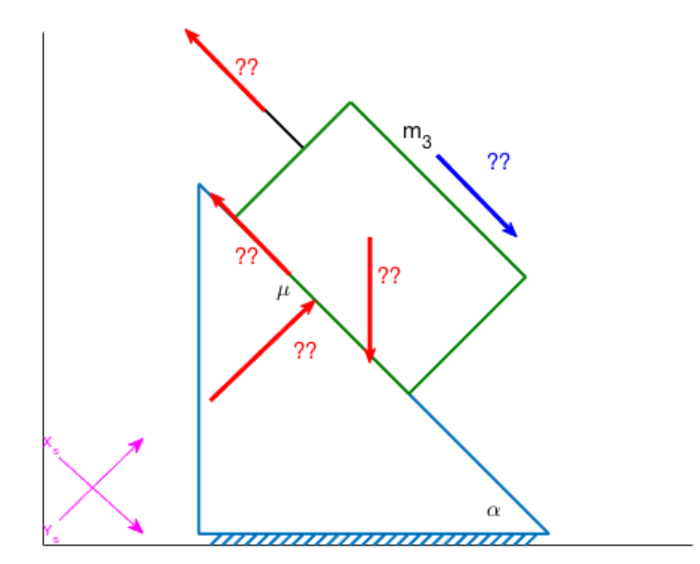

**According to the symbols adopted in line %(1.1), please fill in the linear acceleration of the 3rd element:**

p8='a3';

**Please substitute the symbol describing the weight of the 3rd element:**

F12='Q3';

**Please fill in the substrate reaction, according to the symbols adopted in line %(1.6):**

F13='N3';

**Please fill in the friction force, according to the symbols adopted in line %(1.5):**

F14='T3';

**According to the symbols shown in Figure 3, please fill in the tension force in the chord connected to the 2nd element:**

F15='S4';

Free Body Diagram of the 2nd element is shown in Figure 4. 

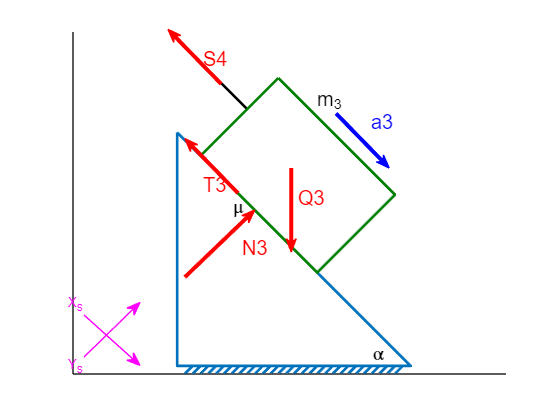

Fig 4. Free body diagram of the 3rd element


draw_3;

## The Equation of Friction

The equation of friction relates the friction with the substrate reaction force. 

**Please fill in right side of the following equation:**

L=T3;
P=mu*N3;
feq7=(L==P);

## Dynamic equations of motion

It is convenient to write the equations of forces according to the X_s and Y_s axis, related to the inclined plane. 

**Please fill in the left and right side of the equation, describing the X_s component of the resultant force acting on the 3rd element:**

L=-T3-S4+Q3*sin(alpha);
P=a3*m3;
feq8=(L==P);

**Please fill in the left side of the equation, describing the Y_s component of the resultant force acting on the 3rd element:**

L=N3-Q3*cos(alpha);
P=sym(0);
feq9=(L==P);

Checking of the equations:

test3;

# The 4th Element 

## Free Body Diagram

The 4th element is the block hanging freely from the pulley

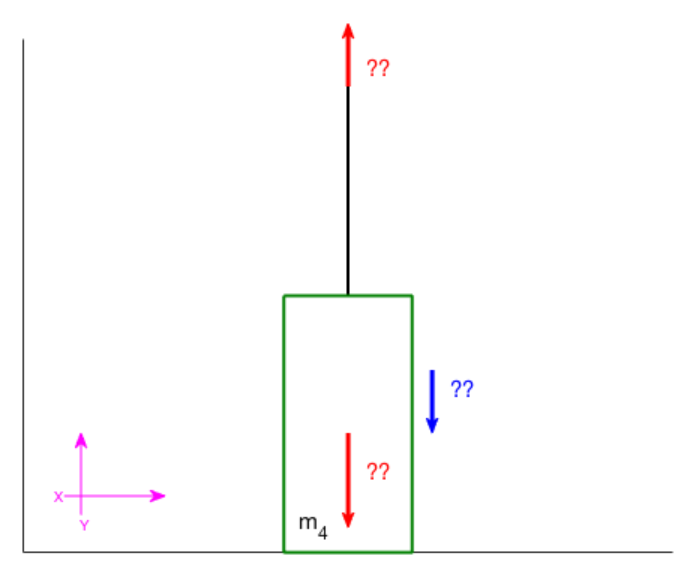

**According to the symbols adopted in line %(1.1), please fill in the linear acceleration of the 4th element:**

p9='a4';

**According to the symbols shown in Figure 2, please  fill in the tension force in the chord connected to the 1st element:**

F16='S2';

**Please substitute the symbol describing the weight of the 4th element:**

F17='Q4';

Free Body Diagram of the 2nd element is shown in Figure 5.

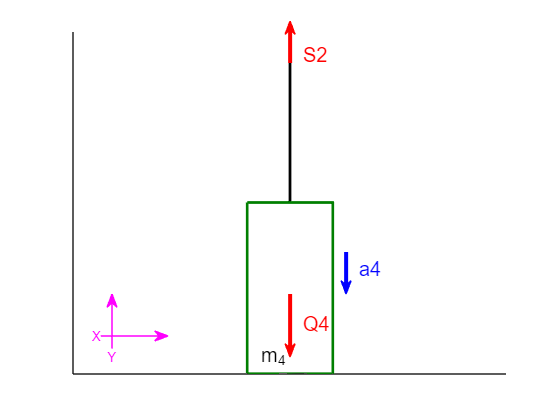

Fig 5. Free body diagram of the 4th element


draw_4;

## Dynamic equation of motion

The block has only one degree of freedom in Y direction.

**Fill in the left and right side of the equation, describing the Y component of the resultant force acting on the 4th element:**

L=S2-Q4;
P=-a4*m4;
feq10=(L==P);

Checking of the equations:

test4;

# The 5th Element

## Free Body Diagram

The last element of the system is the hanging pulley beeing able to move in the vertical direction. The pulley is suported by two chords. One of the chords is atached to fixed ceilling, the second to  the 1st element. The linear acceleration of the chord fixed to the ceilling is equal to zero, while the linear acceleration of the chorde connected to the 1st element is not zero

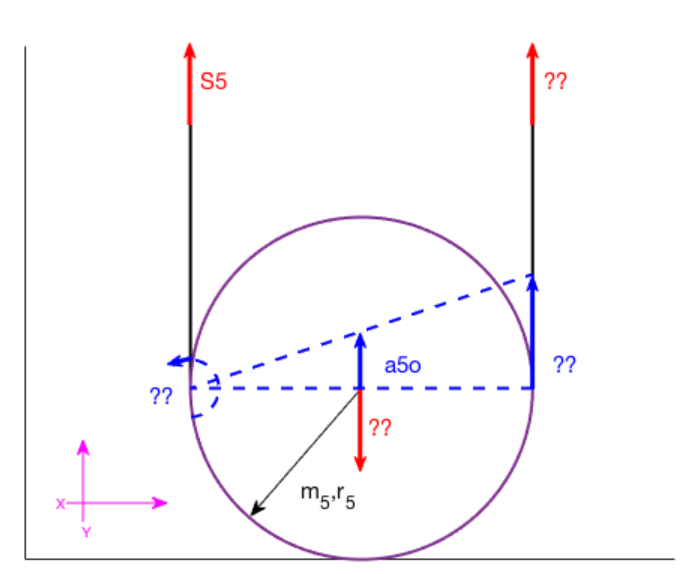 

**According to the symbols adopted in line %(1.1), please fill in the angular acceleration of the 5th element:**

p10='e5';

According to the symbols adopted in line %(1.1) the linear acceleration of the mass center of 5th element is equal:

p11='a5o';

**According to the symbols adopted in line %(1.1) and Figure 2 fill in the linear acceleration of the chorde connected to the right edge of the pulley:**

p12='a5';

**Please substitute the symbol describing the weight of the 5th element:**

F18='Q5';

**According to the symbols shown in Figure 2. and line %(1.4) fill in the tension force in the chord connected to the 1st element:**

F19='S5';
F20='S3';

Free Body Diagram of the 2nd element is shown in Figure 6.

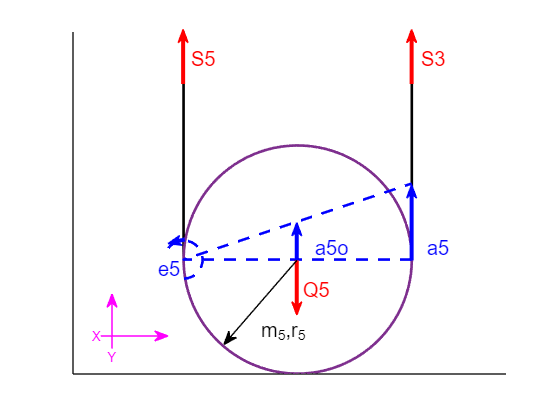

Fig 6. Free body diagram of the 5th element


draw_5;

## Dynamic equations of motion

The 5th element can move in a vertical direction and can rotate around mass center overlapping the pulleys symmetry axis. 

**Fill in the left and right side of the equation, describing the vertical component of the resultant force acting on the 5th element:**

L=S3+S5-Q5;
P=m5*a5o;
feq11=(L==P);

**Fill in the left and right side of the equation, describing the resultant moments of force acting on the 5th element:**

L=S3*r5-S5*r5;
P=I5*e5;
feq12=(L==P);

## Kinematic equations of motion

**Fill in the right side of the kinematic equation, connecting the angular acceleration of the 5th element and linear acceleration of the chord **$a_{5}$:

L=a5;
P=2*e5*r5;
keq6=(L==P);

**Fill in the right side of the kinematic equation, connecting the linear acceleration of the mass center of the 5th **$a_{5o}$**element and linear acceleration of the chord **$a_{5}$:

L=a5;
P=2*a5o;
keq7=(L==P);

Checking of the equations:

test5;

# Summary of Equations of Motions

As a result of the **dynamical analysis** of the system we have **19 equations** connecting **19 unknowns** variables. The system is therefore dynamically determinable.

dispEqations

*********************************************
* Equations of forces of 1 element (3 eq.): *
*********************************************


$$\mathrm{R1x}+S_{1}=0$$

$$\mathrm{R1y}-S_{2}-S_{3}-M_{1}\,g-g\,m_{1}=0$$

$$R_{1}\,S_{3}-R_{1}\,S_{1}-S_{2}\,r_{1}=-e_{1}\,\left(\frac{M_{1}\,{R_{1}}^{2}}{2}+\frac{m_{1}\,{r_{1}}^{2}}{2}\right)$$

*********************************************
* Equations of motion of 2 element (3 eq.): *
*********************************************


$$\mathrm{R2x}-S_{1}+S_{4}\,\cos\left(\alpha \right)=0$$

$$\mathrm{R2y}-g\,m_{2}-S_{4}\,\sin\left(\alpha \right)=0$$

$$S_{1}\,r_{2}-S_{4}\,r_{2}=-\frac{e_{2}\,m_{2}\,{r_{2}}^{2}}{2}$$

*********************************************
* Equations of motion of 3 element (2 eq.): *
*********************************************


$$N_{3}-g\,m_{3}\,\cos\left(\alpha \right)=0$$

$$g\,m_{3}\,\sin\left(\alpha \right)-T_{3}-S_{4}=a_{3}\,m_{3}$$

*********************************************
* Equations of motion of 4 element (1 eq.): *
*********************************************


$$S_{2}-g\,m_{4}=-a_{4}\,m_{4}$$

*********************************************
* Equations of motion of 5 element (2 eq.): *
*********************************************


$$S_{3}+S_{5}-g\,m_{5}=\mathrm{a5o}\,m_{5}$$

$$S_{3}\,r_{5}-S_{5}\,r_{5}=\frac{e_{5}\,m_{5}\,{r_{5}}^{2}}{2}$$

***********************************************************
* Equations of kinematic constrains of 1 element (3 eq.): *
***********************************************************


$$R_{1}\,e_{1}=a_{2}$$

$$e_{1}\,r_{1}=a_{4}$$

$$R_{1}\,e_{1}=a_{5}$$

***********************************************************
* Equations of kinematic constrains of 2 element (2 eq.): *
***********************************************************


$$e_{2}\,r_{2}=a_{2}$$

$$e_{2}\,r_{2}=a_{3}$$

***********************************************************
* Equations of kinematic constrains of 5 element (2 eq.): *
***********************************************************


$$a_{5}=2\,e_{5}\,r_{5}$$

$$a_{5}=2\,\mathrm{a5o}$$

*********************************************
* Equation of friction of 3 element (1 eq): *
*********************************************


$$T_{3}=N_{3}\,\mu$$

Connecting all equations and eliminating all unknown except $\epsilon_{1}$ we get the following equation, describing the angular acceleration of the 1st element of the system:

disp(e1s);

$$-\frac{4\,g\,\left(R_{1}\,m_{5}-2\,m_{4}\,r_{1}-2\,R_{1}\,m_{3}\,\sin\left(\alpha \right)+2\,R_{1}\,m_{3}\,\mu \,\cos\left(\alpha \right)\right)}{4\,M_{1}\,{R_{1}}^{2}+4\,{R_{1}}^{2}\,m_{2}+8\,{R_{1}}^{2}\,m_{3}+3\,{R_{1}}^{2}\,m_{5}+4\,m_{1}\,{r_{1}}^{2}+8\,m_{4}\,{r_{1}}^{2}}$$

# Task Parametrisation

The considered dynamic system is located in the Earth's gravitational field. The earth acceleration has the constant value of:

gv=9.81*u.m*u.s^-2;

**Please substitute any values of mass parameters and radii of the systems pulleys and blocks:**

m1v=8*u.kg;
M1v=20*u.kg;
m2v=8*u.kg;
m3v=2*u.kg;
m4v=2*u.kg;
m5v=10*u.kg;
r1v=5*u.m;
R1v=13*u.m;
r2v=2*u.m;
r5v=5*u.m;
muv=0.5;
sym=[g,  mu, m1,  M1,  m2,  m3,  m4,  m5, r1,  R1,  r2, r5];
val=[gv, muv, m1v, M1v, m2v, m3v, m4v, m5v, r1v, R1v, r2v, r5v];
e1p_alpha=subs(e1s, sym, val);
disp(e1p_alpha)

$$-\frac{981\,\left(110\,\mathrm{kg}\,m+26\,\cos\left(\alpha \right)\,\mathrm{kg}\,m-52\,\sin\left(\alpha \right)\,\mathrm{kg}\,m\right)}{697550}\,\frac{1}{\mathrm{kg}\,m\,s^{2}}$$

**In the next step please examine, the value of acceleration **$\epsilon_{1}$** as a function of inclination angle **$\alpha$**:**

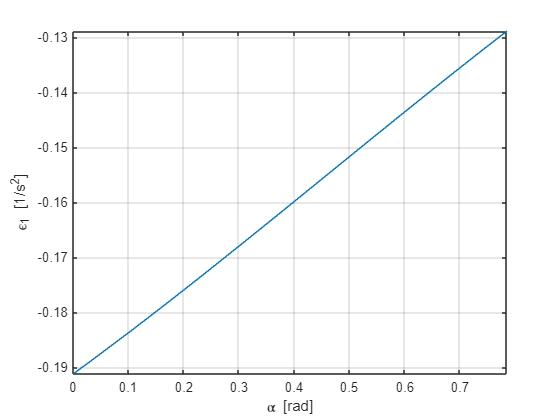

[e1v,e1u]=separateUnits(e1p_alpha);
figure;
fplot(e1v,[0, deg2rad(45)]);
grid on;
xlabel('\alpha [rad]');
ylabel('\epsilon_{1} [1/s^2]');

**Then fill in the selected value of the angle of inclination **$\alpha  \in  <0^\circ, 45^\circ>$**:**

alphav=deg2rad(60);
e1v=subs(e1p_alpha, alpha, alphav);

# The solution

Given the the value of **angular acceleration** of the 1st element:

disp(simplify(e1v));

$$\frac{25506\,\sqrt{3}-120663}{697550}\,\frac{1}{s^{2}}$$

we can count the **angular velocity** of the 1st pulley:

syms omega(t);
T=t*u.s;
difeq=(e1v==diff(omega,T))

$$difeq(t) = -\frac{981\,\left(123\,\mathrm{kg}\,m-26\,\sqrt{3}\,\mathrm{kg}\,m\right)}{697550}\,\frac{1}{\mathrm{kg}\,m\,s^{2}}=\frac{\partial }{\partial t}\omega \left(t\right)\,\frac{1}{s}$$

**Select value of the boundary condition:**

cond=(omega(0)==0.1/u.s);

The function describing the angular velocity has the following form:

omega_v=(omega==dsolve(difeq,cond))

$$omega\_v(t) = \omega \left(t\right)=\frac{25506\,\sqrt{3}\,t-120663\,t+69755}{697550}\,\frac{1}{s}$$

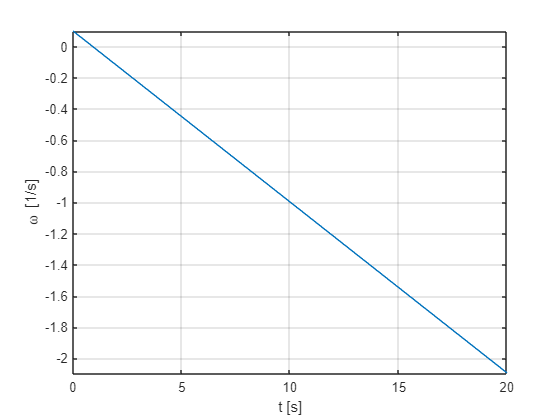

[o_v, o_u]=separateUnits(rhs(omega_v));
figure;
fplot(o_v, [0,20]);
grid on;
xlabel('t [s]');
ylabel('\omega [1/s]');

Analogous we can count the **angular road** of the 1st pulley:

syms phi(t);
difeq=(o_v==diff(phi,T)*u.s)

$$difeq(t) = \frac{12753\,\sqrt{3}\,t}{348775}-\frac{120663\,t}{697550}+\frac{1}{10}=\frac{\partial }{\partial t}\varphi \left(t\right)$$

**Select value of the boundary condition:**

cond=phi(0)==-1;

The function describing the angular road has the following form:

phi_v=(phi==dsolve(difeq,cond))

$$phi\_v(t) = \varphi \left(t\right)=\left(\frac{12753\,\sqrt{3}}{697550}-\frac{120663}{1395100}\right)\,t^{2}+\frac{t}{10}-1$$

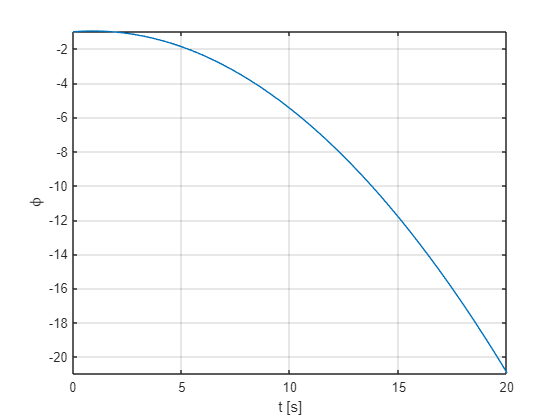

[p_v, p_u]=separateUnits(rhs(phi_v));
figure;
fplot(p_v, [0,20]);
grid on;
xlabel('t [s]');
ylabel('\phi');

That is THE END of the task solution. 